# ***Battery State of Charge Estimation using Extended Kalman Filter***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini, Haris Al-Qodri Maarif, Ahmad Husin Lubis, Danny Mokhammad Gandana

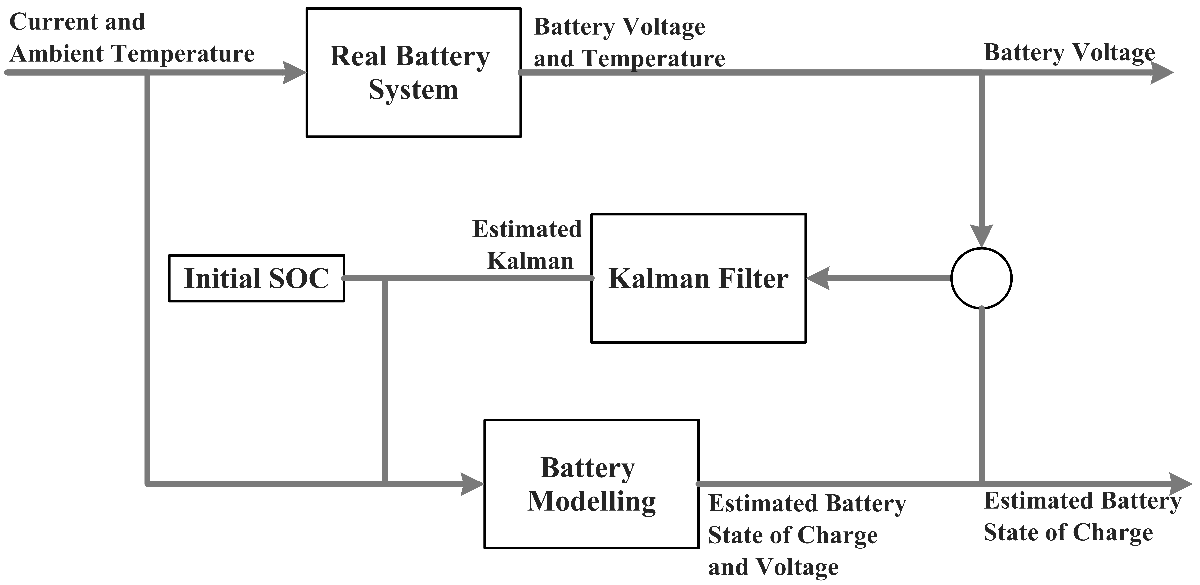

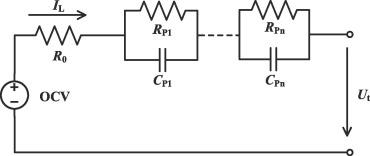

The DSP_EKF_SOC_Estimation function estimates a battery's terminal voltage (Vt) and state of charge (SOC) using a second order RC equivalent circuit model (ECM) and extended Kalman Filter (EKF). The function takes the following as inputs:

- measured drive cycle current (A)

- measured drive cycle terminal voltage (V)

- battery temperature (C)

Outputs of the function are:

- estimated SOC

- estimated terminal voltage

- SOC Error

- terminal voltage error

- RMSE of terminal voltage and SOC

function [SOC_Estimated, Vt_Estimated, Vt_Error] = DSP_EKF_SOC_Estimation(Current, Vt_Actual, Temperature)
load 'BatteryModel2RCtest.mat';
load 'SOC-OCV.mat'; % Load the SOC-OCV curve

The battery parameters $R0$ to $C2$ were estimated from HPPC or other charaterization tests using the Modeling Batteries Using Simulink and Simscape simulation from the series: [Hybrid Electric Vehicles](https://www.mathworks.com/videos/series/hybrid-electric-vehicles.html) resource available at https://www.mathworks.com/videos/modeling-batteries-using-simulink-and-simscape-1562930245321.html.

$T$ is the measured battery temperature taken at time of the characterization and drive cycle tests.

### Modeled Battery Parameters Initialization

The $scatteredInterpolant$ function performs interpolation on either 2-D or 3-D set of scattered data which is returned as a function. This function is then evaluated each step given that steps temperature and SOC. If there is no temperature data or single temperature data, the $scatteredInterpolant$ can be replaced with $pchip$, an example is given below.

SOC_Init    = 1; % intial SOC
X           = [SOC_Init; 0; 0]; % state space x parameter intializations
DeltaT      = 1; % sample time in seconds
Qn_rated    = 3*3600; % Ah to Amp-seconds

Initialize 2D-Interpolant functions for battery parameters and SOC-OCV curve, this function also allows for extrapolation

F_R0    = scatteredInterpolant(param.T,param.SOC,param.R0);
F_R1    = scatteredInterpolant(param.T,param.SOC,param.R1);
F_R2    = scatteredInterpolant(param.T,param.SOC,param.R2);
F_C1    = scatteredInterpolant(param.T,param.SOC,param.C1);
F_C2    = scatteredInterpolant(param.T,param.SOC,param.C2);
F_OCV   = scatteredInterpolant(param.T,param.SOC,param.OCV);
% OCV can be extrapolated using the same method or through the polyfit function

Fit an odd-order polynomial to the entirety of the SOC-OCV data. This means that only one curve is being used for all the temperatures. For calcuating the C matrix this is required since the $polyder$ function is utilized, however, for calculating the terminal voltage, the $scatteredInterpolant$ function can be used.

SOCOCV  = polyfit(SOC_OCV.SOC,SOC_OCV.OCV,11); % calculate 11th order polynomial for the SOC-OCV curve 
dSOCOCV = polyder(SOCOCV); % derivative of SOC-OCV curve for matrix C

The Kalman Filter has 3 parameters that can vary: $R$, $P$ and $Q$. These will need to be adjusted/tuned for each battery either manually or through an optimization algorithm. $R$ should be set to the square of the error from the equipment used to test the battery cell. Once the value of $Q$ has been tuned, $R$ cannot be updated. 

n_x   = size(X,1);
R_x   = 1e-11;
P_x   = [1e-5 0 0; 0 1e-5 0; 0 0 1e-5];
Q_x   = [1e-15 0 0; 0 1e-10 0; 0 0 1e-10];

Initialize the output vectors and set the length of the for loop based on the size of the current vector.

SOC_Estimated   = [];
Vt_Estimated    = [];
Vt_Error        = [];
ik              = length(Current);
Current         = Current - 10;
Temperature     = Temperature + 5;

## Kalman Filter Algorithm

This is the start of the Extended Kalman Filter algorithm. The loop runs through the length of the data based on the current input.

for k = 1:ik
    T           = Temperature(k);
    U           = Current(k);
    SOC         = X(1);
    V1          = X(2);
    V2          = X(3);

Evaluate the battery parameter scatteredInterpolant 

    R0     = F_R0(SOC,T);
    R1     = F_R1(SOC,T);
    R2     = F_R2(SOC,T);
    C1     = F_C1(SOC,T);
    C2     = F_C2(SOC,T);
    OCV    = F_OCV(SOC,T);
    %OCV    = pchip(param.SOC,param.OCV,SOC); % pchip sample for unknown or single temperature
    
    OCV = polyval(SOCOCV,SOC); % calculate the values of OCV at the given SOC, using the polynomial SOCOCV

The following is used to calculate the A and B matrices below on line 70 and 73.

    Tau_1       = C1 * R1;
    Tau_2       = C2 * R2;

    a1 = exp(-DeltaT/Tau_1);
    a2 = exp(-DeltaT/Tau_2);
    
    b1 = R1 * (1 - exp(-DeltaT/Tau_1));
    b2 = R2 * (1 - exp(-DeltaT/Tau_2)); 

### Run Update Model

Vt equation is based on:


$$V_t = V_{OC} - V_1 - V_2 - iR_1$$
 

    TerminalVoltage = OCV - V1 - V2 + (R0.*U);

When $U$ (current) is positive and $U$ is negative, the battery is charging. The coulombic efficiency ($\eta$) is set to 1 for lithium-ion batteries but could be less than 1 for lead-acid batteries. Change $eta$ as required.

    if U > 0
        eta = 1; % eta for discharging
    elseif U <= 0 
        eta = 1; % eta for charging
    end

Linearzing the model by linearizing the C matrix. The $polyval$ function returns the value of the polyder function at the selected SOC.


$$JC =  [\frac{\partial V_{OC}}{\partial SOC}   \frac{\partial V}{\partial V_1}  \frac{\partial V}{\partial V_2} ]
	= [\frac{\partial V_{OC}}{\partial SOC}  -1  -1 ]$$


    dOCV = polyval(dSOCOCV, SOC);
    C_x    = [dOCV -1 -1];

Calculate the Vt error.

    Error_x   = Vt_Actual(k) - TerminalVoltage;

Save/update the SOC and voltage estimates in a vector with the Vt error. These are the output vectors of the function.

    Vt_Estimated    = [Vt_Estimated;TerminalVoltage];
    SOC_Estimated   = [SOC_Estimated;SOC];
    Vt_Error        = [Vt_Error;Error_x];

### Extended Kalman Filter Algorithm

EKF uses a two-step prediction-correction algorithm. Calculate the A and B matrices using the variables from above:

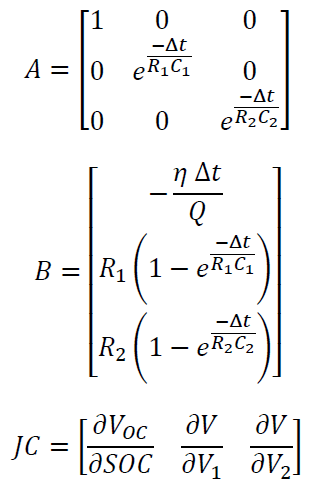

Next, complete the prediction (time update) portion of the KF. 

1. Project the states ahead (a-priori):

2. Project the error covariance ahead:

    A   = [1 0 0; 0 a1 0; 0 0 a2];
    B   = [-(eta * DeltaT/Qn_rated); b1; b2];
    X   = (A.*X) + (B.*U);
    P_x = (A.*P_x.*A') + Q_x;

Next, complete the correction (measurement update) portion of the KF.

1. Compute the Kalman gain:

2. Update estimate with measurement $z_k$ (a-posteriori):

3. Update error covariance:

    KalmanGain_x = (P_x).*(C_x').*(inv((C_x.*P_x.*C_x') + (R_x)));
    X            = X + (KalmanGain_x.*Error_x);
    P_x          = (eye(n_x,n_x) - (KalmanGain_x.*C_x)).*P_x;
end